### Inputs:

clear;
clc;

Lx = 25 * 10^-3; %(m)
Ly = 100 * 10^-3; %(m)
kx = 7; %(W/mK)
ky = 14; % W/mK
qdot = 250000; %W/m^3
Tinf = 25+273; %C
hyArr = [10, 30, 50, 70, 100];
hx = 100; %(W/m^2K)

### Part A: Grid Independence

hy = 10;
T0_old = 1000000;
T0_new = 100; % Starting values so it'll fail

M = 3; % Starting number of horizontal grid points
N = 3; % Starting number of vertical grid points

% Surface temps
Tsx = Tinf + (qdot * Ly / hx);
Tsy = Tinf + (qdot * Lx / hy);

error = abs(T0_old - T0_new) / T0_old;
while (error > 0.02)
    M = round(M * sqrt(1.5));
    N = round(N * sqrt(1.5));
    gridsize = M*N;
    dx = Lx / (M-1);
    dy = Ly / (N-1);

    % Calculate T0_new with matrix
    unknowns = M*N-M-N+1;
    A = zeros(unknowns, unknowns);
    b = zeros(unknowns, 1);

    for i = 1:N-1
        for j = 1:M-1
            % Make the point have a number depending on its location
            point = (M - 1) * (i - 1) + j;
            A(point,point) = -(2*kx*dy/dx + 2*ky*dx/dy);
            
            % Add heat generation
            b(point) = -qdot*dx*dy;

            % If in first row or column, add Ts to b matrix
            if i == 1
            b(point) = b(point) - Tsx*ky*dx/dy;
            end
            if j == 1
                b(point) = b(point) - Tsy*kx*dy/dx;
            end

            % Add diagonals
            A(point, point) = -2*kx*dy/dx - 2*ky*dx/dy;

            % If in last column, add double Tm-1,n 
            if j == M-1
                A(point, point-1) = 2*kx*dy/dx;
            else % if not in last column, add Tm+1,n
                A(point,point+1) = kx*dy/dx;
            end
            % If not in first or last column, add Tm-1,n
            if (j~=1 && j~=M-1)
                A(point,point-1) = kx*dy/dx;
            end

            % If in last row, add double Tm,n-1
            if i == N-1
                A(point,point-(M-1)) = 2*ky*dx/dy;
            else % If not in last row, add Tm,n+1
                A(point,point+(M-1)) = ky*dx/dy;
            end
            % If not in first or last row, add Tm-1,n
            if (i~=1 && i~=N-1)
                A(point,point-(M-1)) = ky*dx/dy;
            end
        end
    end
    T = A \ b;
    T = T-273; % K to C
    T0_old = T0_new;
    T0_new = T(end);
    error = abs(T0_old - T0_new) / T0_old;
    TGrid = transpose(reshape(T, [N - 1, M - 1]));
end
fprintf('M = %d, N = %d', M, N);

M = 5, N = 5

### Part B: Line Plots with Varying hy

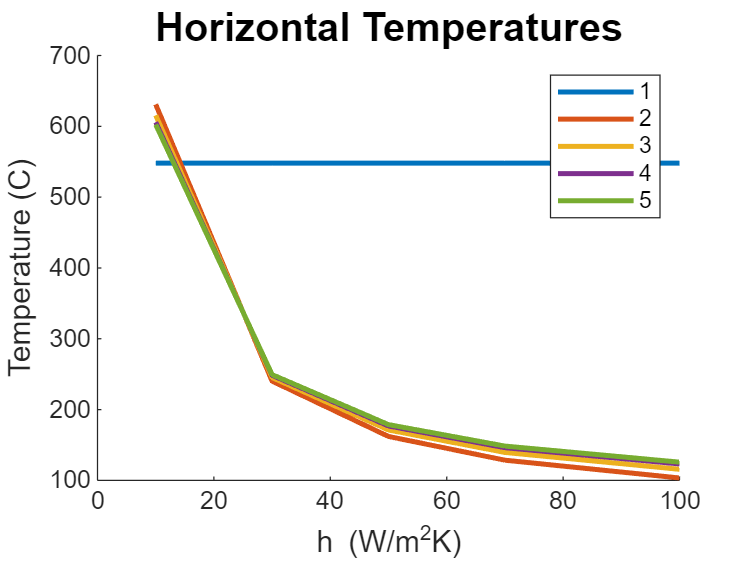

T_horizontal = [];
T_vertical = [];

for hy = hyArr(1:end)
    [T,Tgrid,Th,Tv] = Temps(hy);
    T_horizontal = [T_horizontal; Th];
    T_vertical = [T_vertical; Tv];
end

T_horizontalC = T_horizontal;
T_verticalC = T_vertical;

% horizontal graph
figure
hold on
for i = 1:length(hyArr)
    plot(hyArr(1:end),T_horizontal(:,i), 'LineWidth',2);
end
legend('1','2','3','4','5');
title('Horizontal Temperatures','FontSize',16);
ylabel('Temperature (C)','FontSize',12);
xlabel('h (W/m^2K)','FontSize',12)
hold off

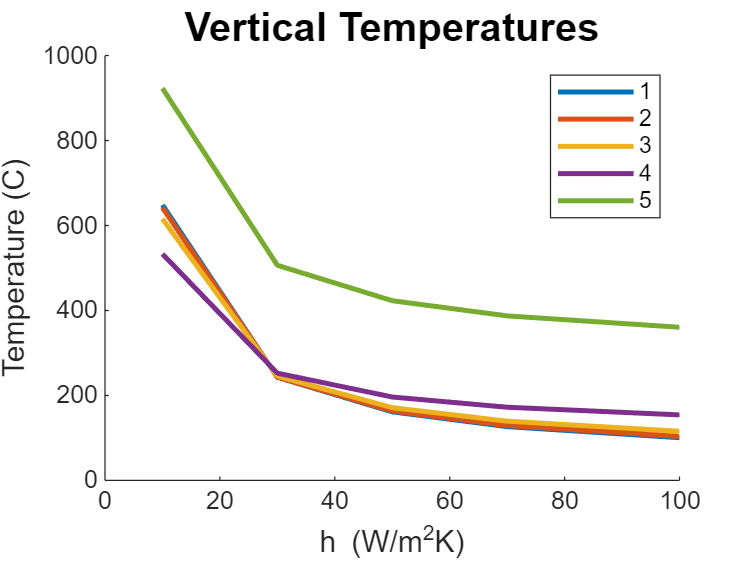

% horizontal graph
figure
hold on
for i = length(hyArr):-1:1
    plot(hyArr(1:end), T_vertical(:,i), 'LineWidth',2);
end
legend('1','2','3','4','5');
title('Vertical Temperatures','FontSize',16);
ylabel('Temperature (C)','FontSize',12);
xlabel('h (W/m^2K)','FontSize',12)
hold off

### Part C: Contour Plots

#### hy = 10 W/m^2 K

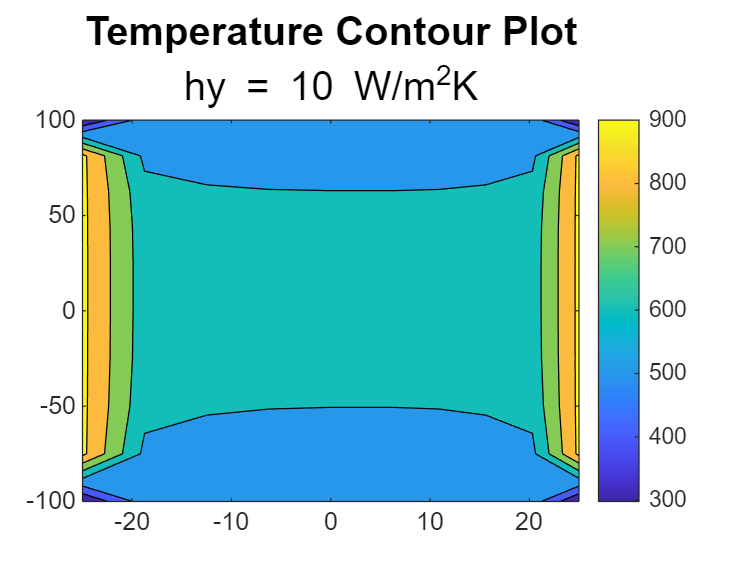

hy = 10; %W/m^2K
[T,Tgrid,Th,Tv] = Temps(hy);
Tdisp = [];
fullTgrid = [Tgrid, flip(Tgrid,2); flip(Tgrid,1),flip(flip(Tgrid,1),2)];

% add surface temps to Tgrid
Tsx = Tinf + (qdot * Ly / hx);
Tsy = Tinf + (qdot * Lx / hy);
xSurface = ones(1,M*2-2)*Tsx;
ySurface = ones(N*2-2,1)*Tsy;
corner = [Tinf];
fullTgrid = [[corner;ySurface;corner], [xSurface; fullTgrid; xSurface], [corner;ySurface;corner]];
x = [linspace(-Lx,0,M),linspace(dx,Lx,M)]*10^3;
y = [linspace(-Ly,0,M),linspace(dy,Ly,N)]*10^3;

% make plot
contourf(x,y,fullTgrid)
colorbar
title({'Temperature Contour Plot'},{'hy = 10 W/m^2K'},'FontSize',16);

disp(fullTgrid);

  298.0000  548.0000  548.0000  548.0000  548.0000  548.0000  548.0000  548.0000  548.0000  298.0000
  923.0000  576.7382  533.0066  509.7971  502.5279  502.5279  509.7971  533.0066  576.7382  923.0000
  923.0000  631.0740  615.6754  605.9110  602.5885  602.5885  605.9110  615.6754  631.0740  923.0000
  923.0000  646.0299  642.1105  639.3279  638.3294  638.3294  639.3279  642.1105  646.0299  923.0000
  923.0000  649.4191  648.2904  647.3116  646.9336  646.9336  647.3116  648.2904  649.4191  923.0000
  923.0000  649.4191  648.2904  647.3116  646.9336  646.9336  647.3116  648.2904  649.4191  923.0000
  923.0000  646.0299  642.1105  639.3279  638.3294  638.3294  639.3279  642.1105  646.0299  923.0000
  923.0000  631.0740  615.6754  605.9110  602.5885  602.5885  605.9110  615.6754  631.0740  923.0000
  923.0000  576.7382  533.0066  509.7971  502.5279  502.5279  509.7971  533.0066  576.7382  923.0000
  298.0000  548.0000  548.0000  548.0000  548.0000  548.0000  548.0000  548.0000  548.0000 

#### hy = 100 W/m^2 K

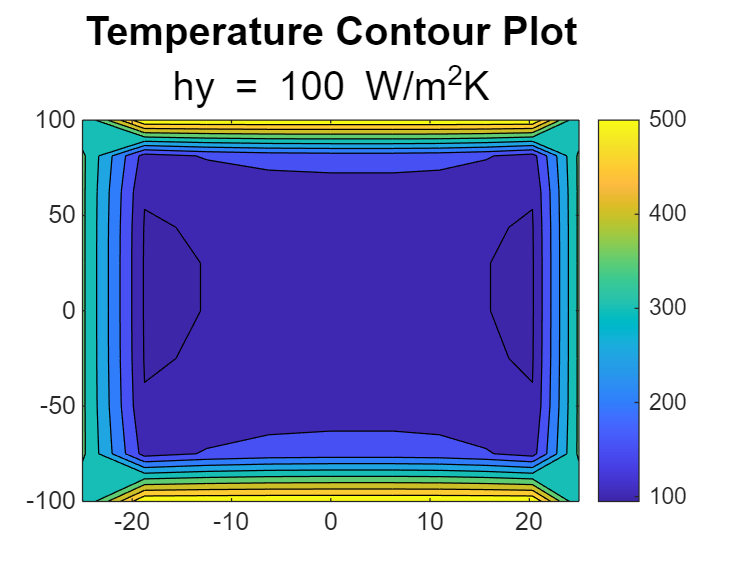

hy = 100; %W/m^2K
[T,Tgrid,Th,Tv] = Temps(hy);
Tdisp = [];
fullTgrid = [Tgrid, flip(Tgrid,2); flip(Tgrid,1),flip(flip(Tgrid,1),2)];

% add surface temps
Tsx = Tinf + (qdot * Ly / hx);
Tsy = Tinf + (qdot * Lx / hy);
xSurface = ones(1,M*2-2)*Tsx;
ySurface = ones(N*2-2,1)*Tsy;
corner = [Tinf];
fullTgrid = [[corner;ySurface;corner], [xSurface; fullTgrid; xSurface], [corner;ySurface;corner]];

figure
contourf(x,y,fullTgrid)
colorbar
title({'Temperature Contour Plot'},{'hy = 100 W/m^2K'},'FontSize',16);

disp(fullTgrid);

  298.0000  548.0000  548.0000  548.0000  548.0000  548.0000  548.0000  548.0000  548.0000  298.0000
  360.5000  129.0926  154.2548  167.7469  171.9963  171.9963  167.7469  154.2548  129.0926  360.5000
  360.5000  103.4682  115.7098  123.2744  125.8225  125.8225  123.2744  115.7098  103.4682  360.5000
  360.5000   96.4952  103.4206  107.7735  109.2569  109.2569  107.7735  103.4206   96.4952  360.5000
  360.5000   94.9196  100.5502  104.0682  105.2648  105.2648  104.0682  100.5502   94.9196  360.5000
  360.5000   94.9196  100.5502  104.0682  105.2648  105.2648  104.0682  100.5502   94.9196  360.5000
  360.5000   96.4952  103.4206  107.7735  109.2569  109.2569  107.7735  103.4206   96.4952  360.5000
  360.5000  103.4682  115.7098  123.2744  125.8225  125.8225  123.2744  115.7098  103.4682  360.5000
  360.5000  129.0926  154.2548  167.7469  171.9963  171.9963  167.7469  154.2548  129.0926  360.5000
  298.0000  548.0000  548.0000  548.0000  548.0000  548.0000  548.0000  548.0000  548.0000 